**Extract all the topics of interest from ROSBAG**


clc
clear
% Specify the directory path where the files are located
directory = 'D:\husky_sysID\dataset_diffTerrain';

% Get the list of file names in the directory
fileList = dir(directory);

% Initialize an empty cell array to store the file names
fileNames = cell(length(fileList), 1);

% Extract file names and store them in the cell array
for i = 1:length(fileList)
    fileNames{i} = fileList(i).name;
end



cd 'D:\husky_sysID\code\MATLABrosbagReader'
% Initialize an empty cell array to store all rosbags
bag = cell(length(fileNames),1);
% Process each file name

for i = 1:length(fileNames)
    % Get the current file name
    fileName = fileNames{i};
    
    % Specify the full file path
    filePath = fullfile(directory, fileName);
    if ~isfile(filePath)
        fprintf('Skipping directory: %s\n', fileName);
        continue
    % Check if the current item is a file (excluding directories)
    else 
        % Add your processing code here
        fprintf('Processing file: %s\n', fileName);
          % Generate the variable name dynamically
        %bagname = sprintf('bag%d', i);
         % Generate each bag struct for the variable
        bag{i} = rosbagReader(filePath);
        
         % Assign the value to the dynamically named variable using eval
        %eval([bagname ' = bag;']);  
    end

end

Skipping directory: .
Skipping directory: ..


Processing file: fsc_v_0.2_m_0002_2023-05-06-14-12-47.bag


Processing file: fsc_v_0.4_m_0002_2023-05-06-14-15-33.bag


Processing file: fsc_v_0.5_m_0006_2023-05-06-15-26-01.bag


Processing file: fsc_v_0.7_m_0006_2023-05-06-15-20-49.bag


Processing file: fsc_v_0.8_m_0004_2023-05-06-14-59-41.bag


Processing file: fsc_v_0.8_m_0006_2023-05-06-15-18-16.bag


Processing file: fsc_v_0.9_m_0006_2023-05-06-15-12-52.bag


Processing file: fsc_v_1_m_0006_2023-05-06-15-09-53.bag


Processing file: fscc_v_0.5_m_0004_2023-05-06-16-01-39.bag


Processing file: fscc_v_0.6_m_0002_2023-05-06-16-19-49.bag


Processing file: fscc_v_0.6_m_0006_2023-05-06-15-32-25.bag


Processing file: fscc_v_0.7_m_0006_2023-05-06-15-35-21.bag


Processing file: fscc_v_0.8_m_0006_2023-05-06-15-37-17.bag


Processing file: fscc_v_1_m_0004_2023-05-06-16-12-27.bag


clf;

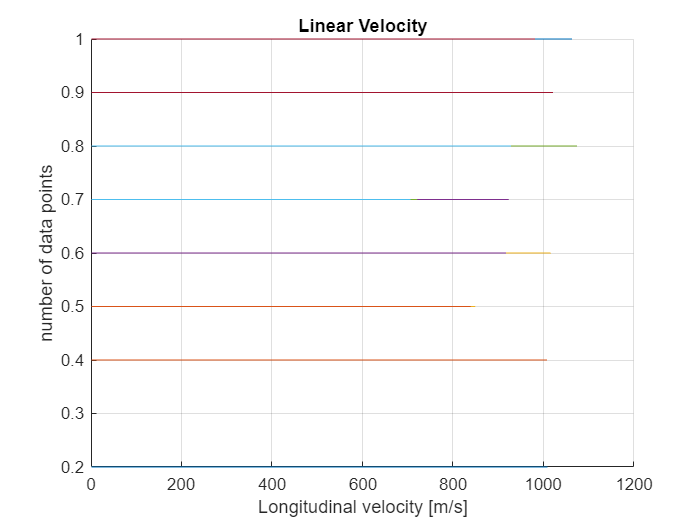

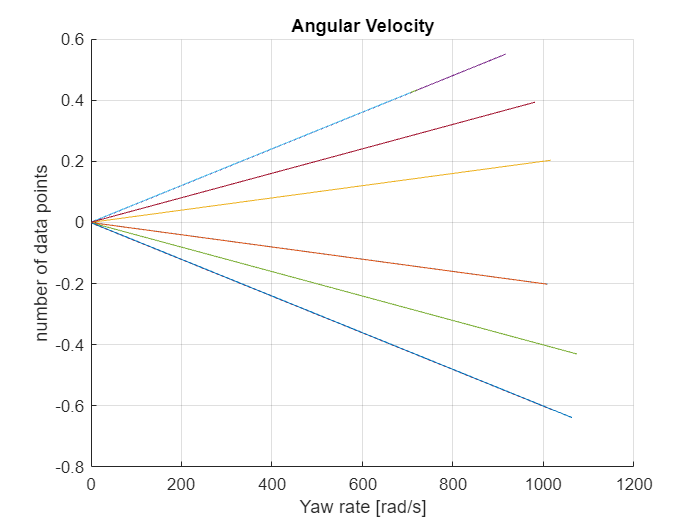


[figure1, figure2] = velocityPlotter(bag);

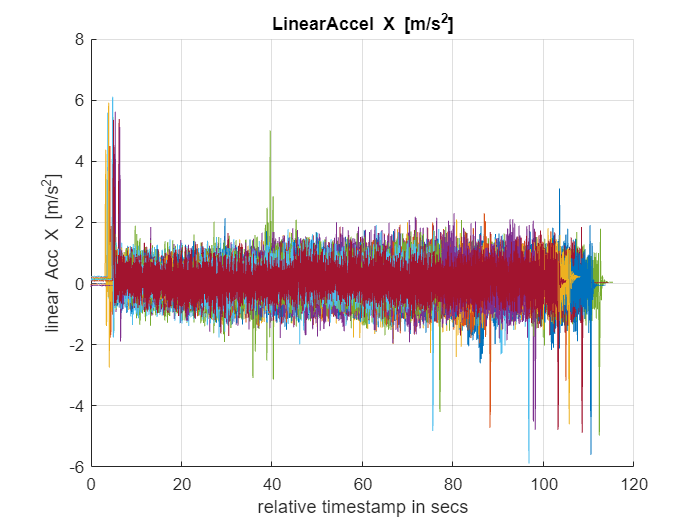

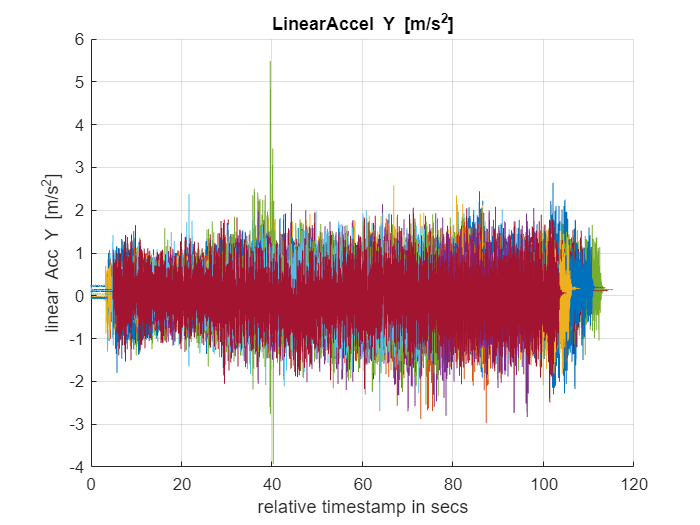

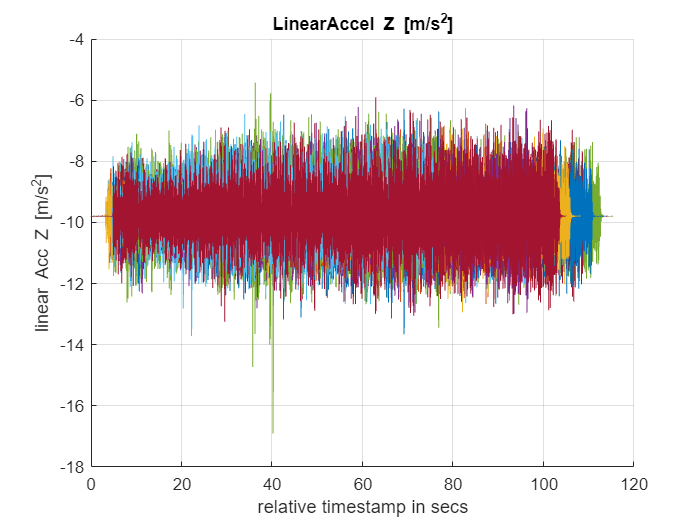


[figure3,figure4,figure5] = plotImuData(bag);

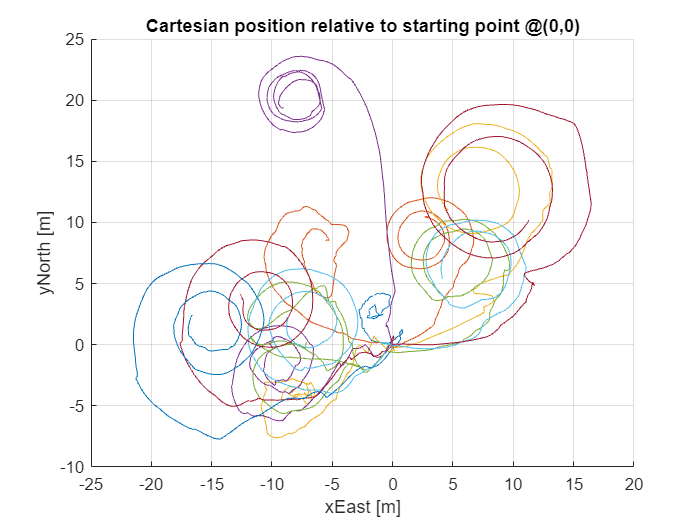

[figure6] = plotGps(bag);